# RSA Encryption/Decryption of Multimedia

*EEE8119*

*Chris Hemingway, Yaw Mensah, Panukorn Wattanajung, Zheliang Geng, Xiaotian Han*

In this demonstration, we encrypt an image with RSA using both Electronic CodeBook (ECB) and Cipher Block Chaining (CBC) encryption.

Other functions in this folder implement the RSA functionality, and should be referenced.

ls rsa_*.m


rsa_decrypt.m      rsa_encrypt.m      rsa_find_primes.m  rsa_keygen.m       



### Pre-Requisites

Clear variables and command window. 

clc; clear;

Import a demo image. Use MATLAB built-in.

We are using a black and white image, of size 256x256. Printout to verify.

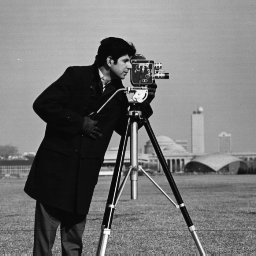

img = imread("cameraman.tif");
    imshow(img);

disp(size(img)); %Get dimensions of image

   256   256



Our RSA library requires the [VariablePrecisionInteger library](https://uk.mathworks.com/matlabcentral/fileexchange/22725-variable-precision-integer-arithmetic) from John D'Errico. This allows us to use integers of length limited only by available memory.

Add this to our path.

addpath(['VariablePrecisionIntegers' filesep 'VariablePrecisionIntegers']);

We have defined these functions to convert VariablePrecisionInteger's to/from text

ls *char*.m 


char2vpi.m  vpi2char.m  



### Generate Primes

We need two prime numbers $p$ and $q$ to generate our keys.

Requirements are that they are of slightly different lengths, and that the product $n=p\times q$is exactly n_bits in length. 

We wrote a function rsa_find_primes to do this, which given a number of bits, returns two suitable primes. Note these are chosen at random, so the same number of bits may return different primes.

Our function rsa_keygen calls this internally, but let's demonstrate it. Drag the slider to change the number of bits.

[p,q] = rsa_find_primes(28)

p = 11467

q = 12511

fprintf("p is prime? = %s \n", string(isprime(p)));

p is prime? = true 


fprintf("q is prime? = %s \n", string(isprime(q)));

q is prime? = true 


The total number of bits of the product $n=p\times \;q$ is

n=p*q;
fprintf("n=%d \t %s",n,dec2bin(n)); %both in decimal and binary

n=143463637 	 1000100011010001010011010101

fprintf("n is %d bits",length(dec2bin(n))); %Number of bits

n is 28 bits

## Generate Keys

Once we have our 2 prime numbers, we can generate the keys. This is done in the function rsa_keygen, which we will describe key features of here. Let's call it now, and time how long it takes for later.

[Kp, Ks] = rsa_keygen(48); %48 bit key as example
disp(Kp); disp(Ks);

    n: 2.2427e+14
    e: 11

    n: 2.2427e+14
    d: 1.2233e+14



Here we refer to the **public** key as $K_p$ and the **private** (secret) key as $K_s$

#### Public/Private Base n

disp (Kp.n);

   2.2427e+14



Our base $n$ is what is used in the modular exponentiation in both encryption and decryption, and is part of the public and private keys. It's definition is simple.

Note that the width of n in bits is commonly referred to as the **size** of our public/private key. This is a parameter we would like to specify, we chose **32 bits** above, lets check that $n$ is actually this value:

ceil(log2(Kp.n))

ans = 48

The strength of RSA relies on it being slow to factorise $n$ into prime factors. For our simple 32 bit key, this can be done relatively quickly. Let's see how long it takes:

tic;
factor(Kp.n);
toc

Elapsed time is 0.118199 seconds.


On my computer (a 2013 Macbook Air), that took 200ms. Quite slow, considering choosing the primes only took ~10ms, 20x faster. 

For practical uses of RSA such as TLS (used in HTTPS),[ 2048 bit key lengths are recommended](https://github.com/ssllabs/research/wiki/SSL-and-TLS-Deployment-Best-Practices#11-use-2048-bit-private-keys), which are consided impractical to factor in reasonable time.

tic;
rsa_find_primes(48);
toc

Elapsed time is 0.008668 seconds.


#### Public Exponent $e$

We need to choose our  **exponent **$e$as part of the public key.

Define the intermediate value $X=\lambda \left(n\right)$, where $\lambda \;$is [Carmicheal's Totient Function](https://en.wikipedia.org/wiki/Carmichael_function)${\lambda \left(n\right)\;\mathrm{returns}\;m\;\mathrm{where}\;a}^m \;\mathrm{mod}\;n=1$. This is the **maximum** possible value of $e$, and $e$ must also be coprime to $X$.

In determining $X$, we can take advantage of $p$ and $q$ being prime, to use a simplification to the Carmicheal function.

(TODO EXPLANATION)


$$X=\left(p-1\right)\times \left(q-1\right)$$


To speed up encryption, it is beneficial if e is a small number (and has a small hamming weight, which is corellated). Therefore, we use a simple algorithm of testing all values between 3 and $X$ ascending for being coprime with $X$. This is shown below.

#### Private Exponent $d$

The private key exponent $d$ is defined from our public exponent $e$ and secret (never used) variable $X$as


$$d\times e\;\mathrm{mod}\;X=1$$


This operation is known as the **modular multiplicative inverse. **

Calculating this is quite involved, so we utilise a function of the VariablePrecisionInteger library to calculate thi

disp(Ks.d);

   1.2233e+14



#### Private Key Base

The base of the private key is actually the same as the base of the private key. 

Kp.n == Ks.n %#ok<EQEFF>

ans = logical
   1


However, we include it in the private key so decryption does not also require the public key.

## Encryption/Decryption

### Algorithm

Encryption of a message in RSA is performed by the algorithm


$$C=P^{e\;} \textrm{mod}\;n$$


Where $P$ is plaintext, $C$is the ciphertext, $e$is the public exponent, and $n$is the public base.

We implement this in the function rsa_encrypt.m. To speed things up, we use a builtin function powermod() from the VariablePrecisionInteger Library

Decryption is given by


$$P=C^d \;\mathrm{mod}\;n$$


This is implemented in rsa_decrypt.m, which again uses the powermod() function to accelerate computation.

### Text Encryption

For a short message, the length is less than the key length

plaintext = 'hello';
key_bits= ceil(log2(Kp.n))

key_bits = 48

plaintext_bits = length(plaintext)*8

plaintext_bits = 40

ciphertext = rsa_encrypt('hello',Kp)

ciphertext =
    90294400605501


Decryption is also easy

decrypted = rsa_decrypt(ciphertext,Ks)

decrypted = 'hello'

However, look what happens when our message is greater than the key length.

plaintext = 'A longer message';
plaintext_bits = length(plaintext)*8

plaintext_bits = 128

ciphertext = rsa_encrypt(plaintext,Kp);
decrypted = rsa_decrypt(ciphertext, Ks);
disp(decrypted);

L]`ÔH


isequal(plaintext, decrypted)

ans = logical
   0


Our message has been corrupted! This is because $\mathrm{if}\;y>n,\;y\;\mathrm{mod}\;n\;\not= y$, and therefore the modulus operation has "truncated" our message.

### Image Size

For our image, the size is much larger than our key length.


$$\mathrm{bits}=\mathrm{width}\times \mathrm{height}\times \mathrm{bits}_\mathrm{per}_\mathrm{pixel}$$


max_pixel_value = double(intmax(class(img)));
bits_per_pixel = ceil(log2(max_pixel_value))

bits_per_pixel = 8

image_bits = numel(img)*bits_per_pixel

image_bits = 524288

disp(key_bits);

    48



Therefore, we need a different approach.

### Electronic Codebook (ECB)

A simple algorithm is Electronic Codebook (ECB) is where each "block" of pixels is encrypted seperately. The block length must be less than our key length.

Lets use quite a short key length of 16 to speed things up, and a basic image.

[Kp, Ks] = rsa_keygen(16);
img = imread("cameraman.tif");

To make the code simple, let 1 block = 1 pixel, therefore our encryption and decryption functions are:

ecb_encrypt = @(pixel) rsa_encrypt(pixel, Kp);
ecb_decrypt = @(pixel) uint8(rsa_decrypt(pixel, Ks, 'isText', false));

Encrypt the image (note quite slow)

tic
encrypted_image = arrayfun(ecb_encrypt, img);
toc

Elapsed time is 5.267384 seconds.


What will the decrypted output look like if there are errors in transmission?

Lets assume a burst error, where one line of the image is changed.

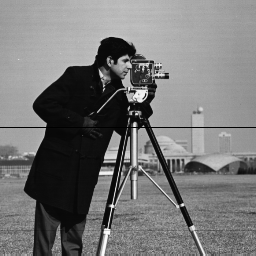

[~, height] = size(encrypted_image);
encrypted_image(height/2,:) = 0; % Clear middle line
decrypted_image = arrayfun(ecb_decrypt, encrypted_image);
imshow(decrypted_image,'InitialMagnification','fit');

This error is clearly visible in the output, but only for the line we modified.

However, electronic codebook has a number of disadvantages. Since the value of every block only depends on the input value of every block

**TODO WRITEUP**

###  Cipher Block Chaining (CBC)

In Cipher Block Chaining, we XOR the plaintext of each block with the previous ciphertext before encryption. The first block is XORd with an initialization vector.

This is more complex to implement, as the message must be able to be padded to a multiple of the cipherblock size. In our particular case, the image is 256x256, so we can split it into 256x64 4 pixel blocks, 

img = imread("cameraman.tif");
disp(size(img)) % Should be 256 256

   256   256



Using a 32 bit key (4 pixels).

[Kp, Ks] = rsa_keygen(32);

Use a fixed initialisation vector (should be random in a real application)

iv = hex2dec('deadbeef');

#### Encryption

Loop through, encrypting groups of 4 blocks

[height, width] = size(img);
encrypted_image = zeros([height,width/4]);
last_block = uint32(iv);

for i=1:height
    for j=1:4:width
        % Combine pixels into block
        block = uint32(0);
        for k=0:3
            block = bitshift(block,8); %Left shift
            block = bitor(block,uint32(img(i,j+k))); % Fill empty bits with pixel value
        end
        % XOR with previous block
        block = bitxor(block, last_block);
        % Encrypt
        encrypted_block = powermod(block, Kp.e, Kp.n); %Speed up by calling powermod directly
        % Save
        output_column = round(j/4) + 1;
        encrypted_image(i,output_column) = encrypted_block;
        last_block = uint32(double(encrypted_block)); %Have to cast to double first
    end
end

Now we corrupt our middle row

encrypted_image(height/2,:) = 255;

#### Decryption

decrypted_image = zeros([height,width]);
last_block = uint32(iv);

for i=1:height
    for j=1:4:width
        input_column = round(j/4) + 1;
        encrypted_block = encrypted_image(i,input_column);
        % Decrypt
        block = powermod(encrypted_block, Ks.d, Ks.n); %Speed up by calling powermod directly
        block = uint32(double(block)); % Convert to uint32
        
        % XOR back
        block = bitxor(block, last_block);
        
        % Save block
        last_block = uint32(double(encrypted_block));
        
        % Split decoded block into pixels
        for k=0:3
            col = j+(3-k); % -k as going in _reverse_ direction per block
            decrypted_image(i,col) = bitand(block, 255);
            block = bitshift(block,-8); % Right shift
        end
    end
end

% Takes a very long time, so play a noise when done
load gong, sound(y,2*Fs)

#### Results

imshow(decrypted_image);